# Generate Figure 7 of the paper "Choice of trimming proportion and number of clusters in robust clustering based on trimming"  

### Luis A. García-Escudero, Christian Hennig, Agustin Mayo Iscar,  Gianluca Morelli, Marco Riani,  

Remark: we assume that you have FSDA installed, at least version 8.7.7.6.

In order to install FSDA in the Home menu, click on Add-Ons and search for FSDA.

## Geyser data

% Load the Geyser dataset and make sure that FSDA is installed
try 
    Y=load('geyser2.txt');
catch
    error('FSDA:missingFSDA','FSDA toolbox is not installed')
end

k = 1:5; % number of groups to test
alphaTrim = 0.00:0.02:0.2; % level of trimmin to test
cc = 50; % restriction factor
nsamp =  1000; % number of  subsets for each k and alpha
nsimul = 100; % number of replicates
crit = 0.05; % p-value threshold

bands=struct;
bands.nsimul=nsimul;
bands.outliersFromUniform = 1;
bands.crit=crit;
[outCTL] = ctlcurves(Y(:,1:end), 'alpha',alphaTrim,'kk',k,'bands',bands, 'restrfactor',cc, 'nsamp',nsamp,'plots',0);

Starting parallel pool (parpool) using the 'Processes' profile ...
04-Mar-2025 22:03:34: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 8 workers.
k=1
k=2
k=3
k=4
k=5
Bands k=1
Bands k=2
Bands k=3
Bands k=4
Bands k=5


disp('Show the Values of p_{k,α}')

Show the Values of p_{k,α}


disp(outCTL.LRTpval)

                  alpha=0    alpha=0.02    alpha=0.04    alpha=0.06    alpha=0.08    alpha=0.1    alpha=0.12    alpha=0.14    alpha=0.16    alpha=0.18    alpha=0.2
                  _______    __________    __________    __________    __________    _________    __________    __________    __________    __________    _________

    k=1_vs_k=2        0            0             0             0             0            0             0             0             0             0            0   
    k=2_vs_k=3        0            0             0             0             0            0        


[~,index]=unique(outCTL.LRTtentSolt.k,'stable');
Solt=outCTL.LRTtentSolt(index,:);
Sol=outCTL.LRTtentSol(index,:);
SolIdx=outCTL.LRTtentSolIDX(:,index);
disp('Show the list of tentative solutions automatically extracted')

Show the list of tentative solutions automatically extracted


disp(Solt(:,1:3))

            index    k    alpha
            _____    _    _____

    Sol1      1      4    0.02 
    Sol2      2      3    0.04 



### Show the solutions automatically found (Figure 7)

Remark: note that in the live version the legends are clickable and it is possible to hide/show the single groups

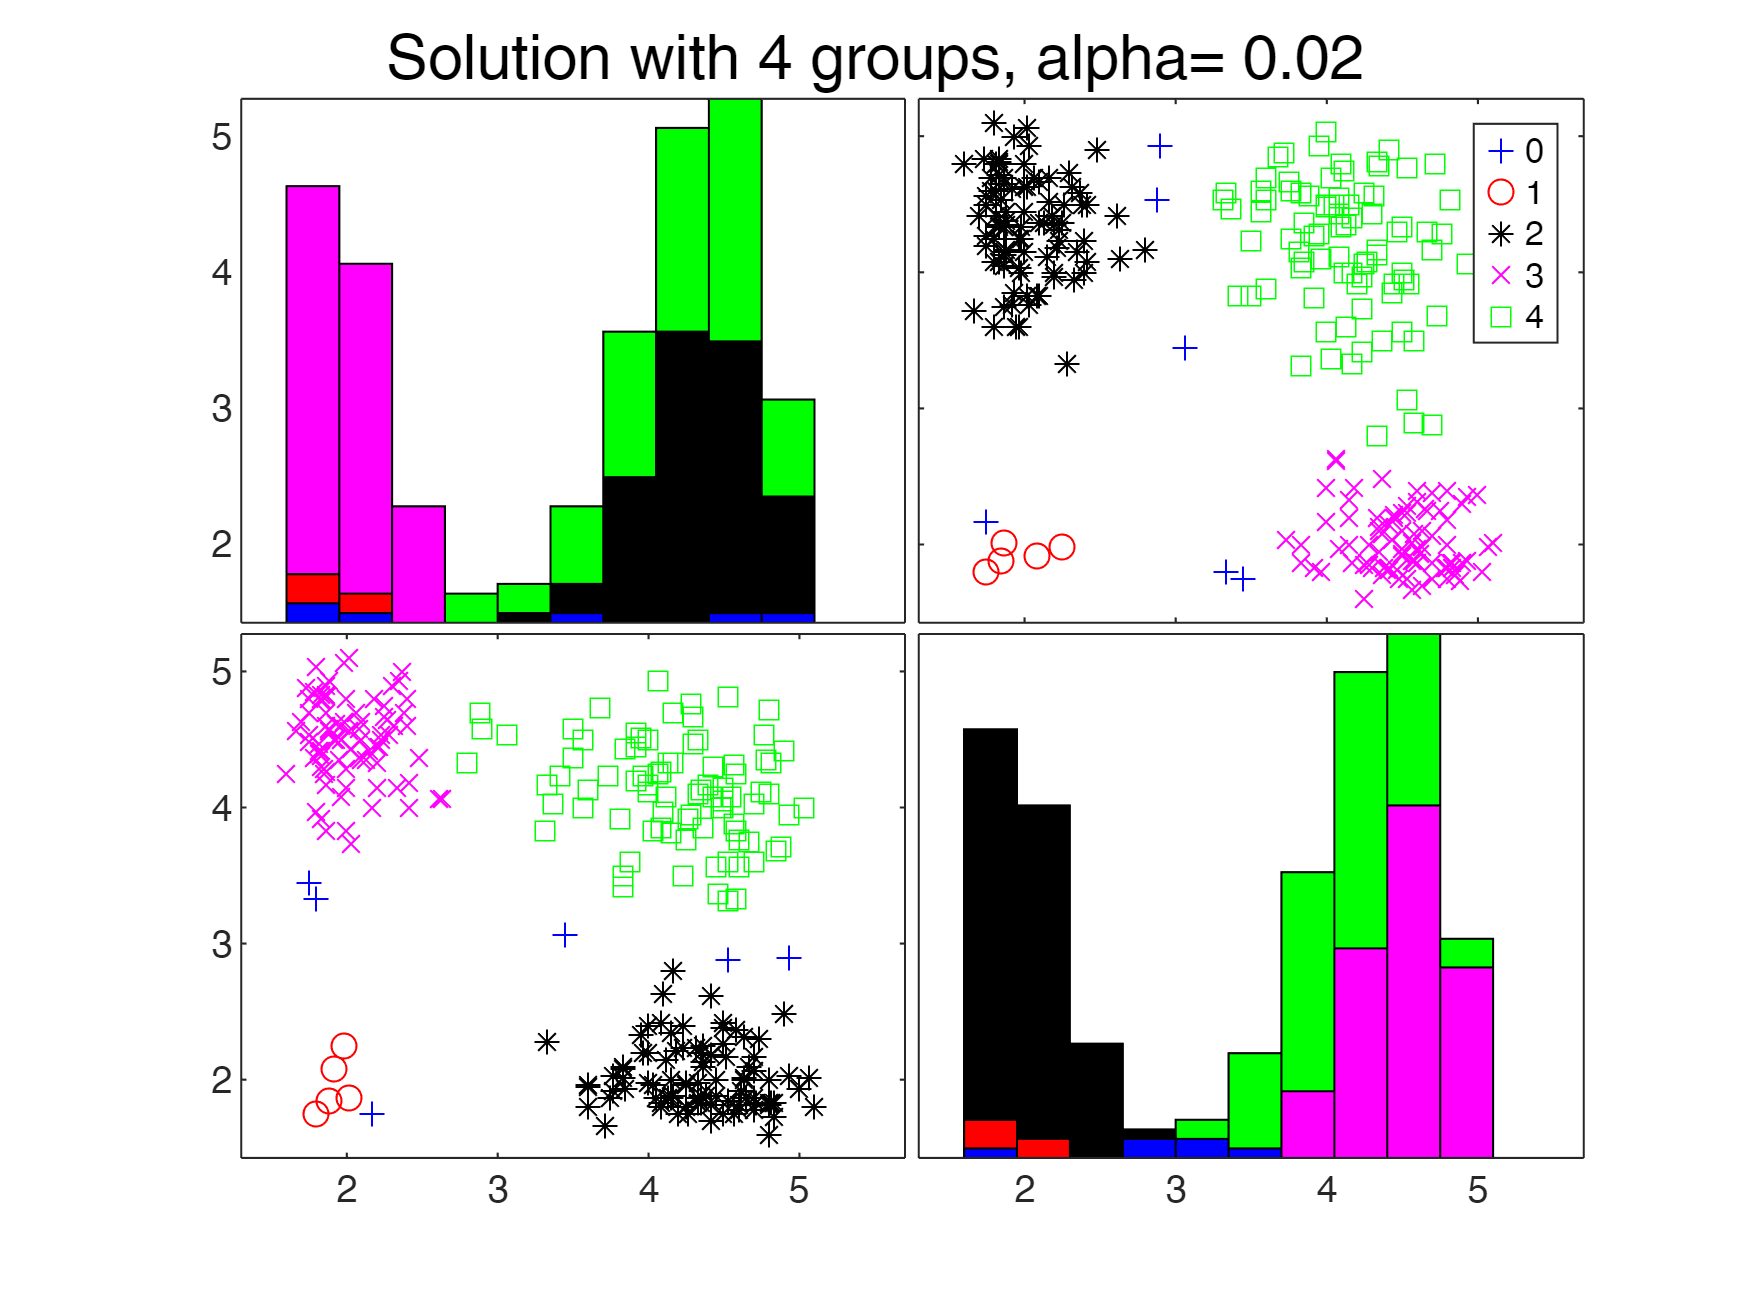

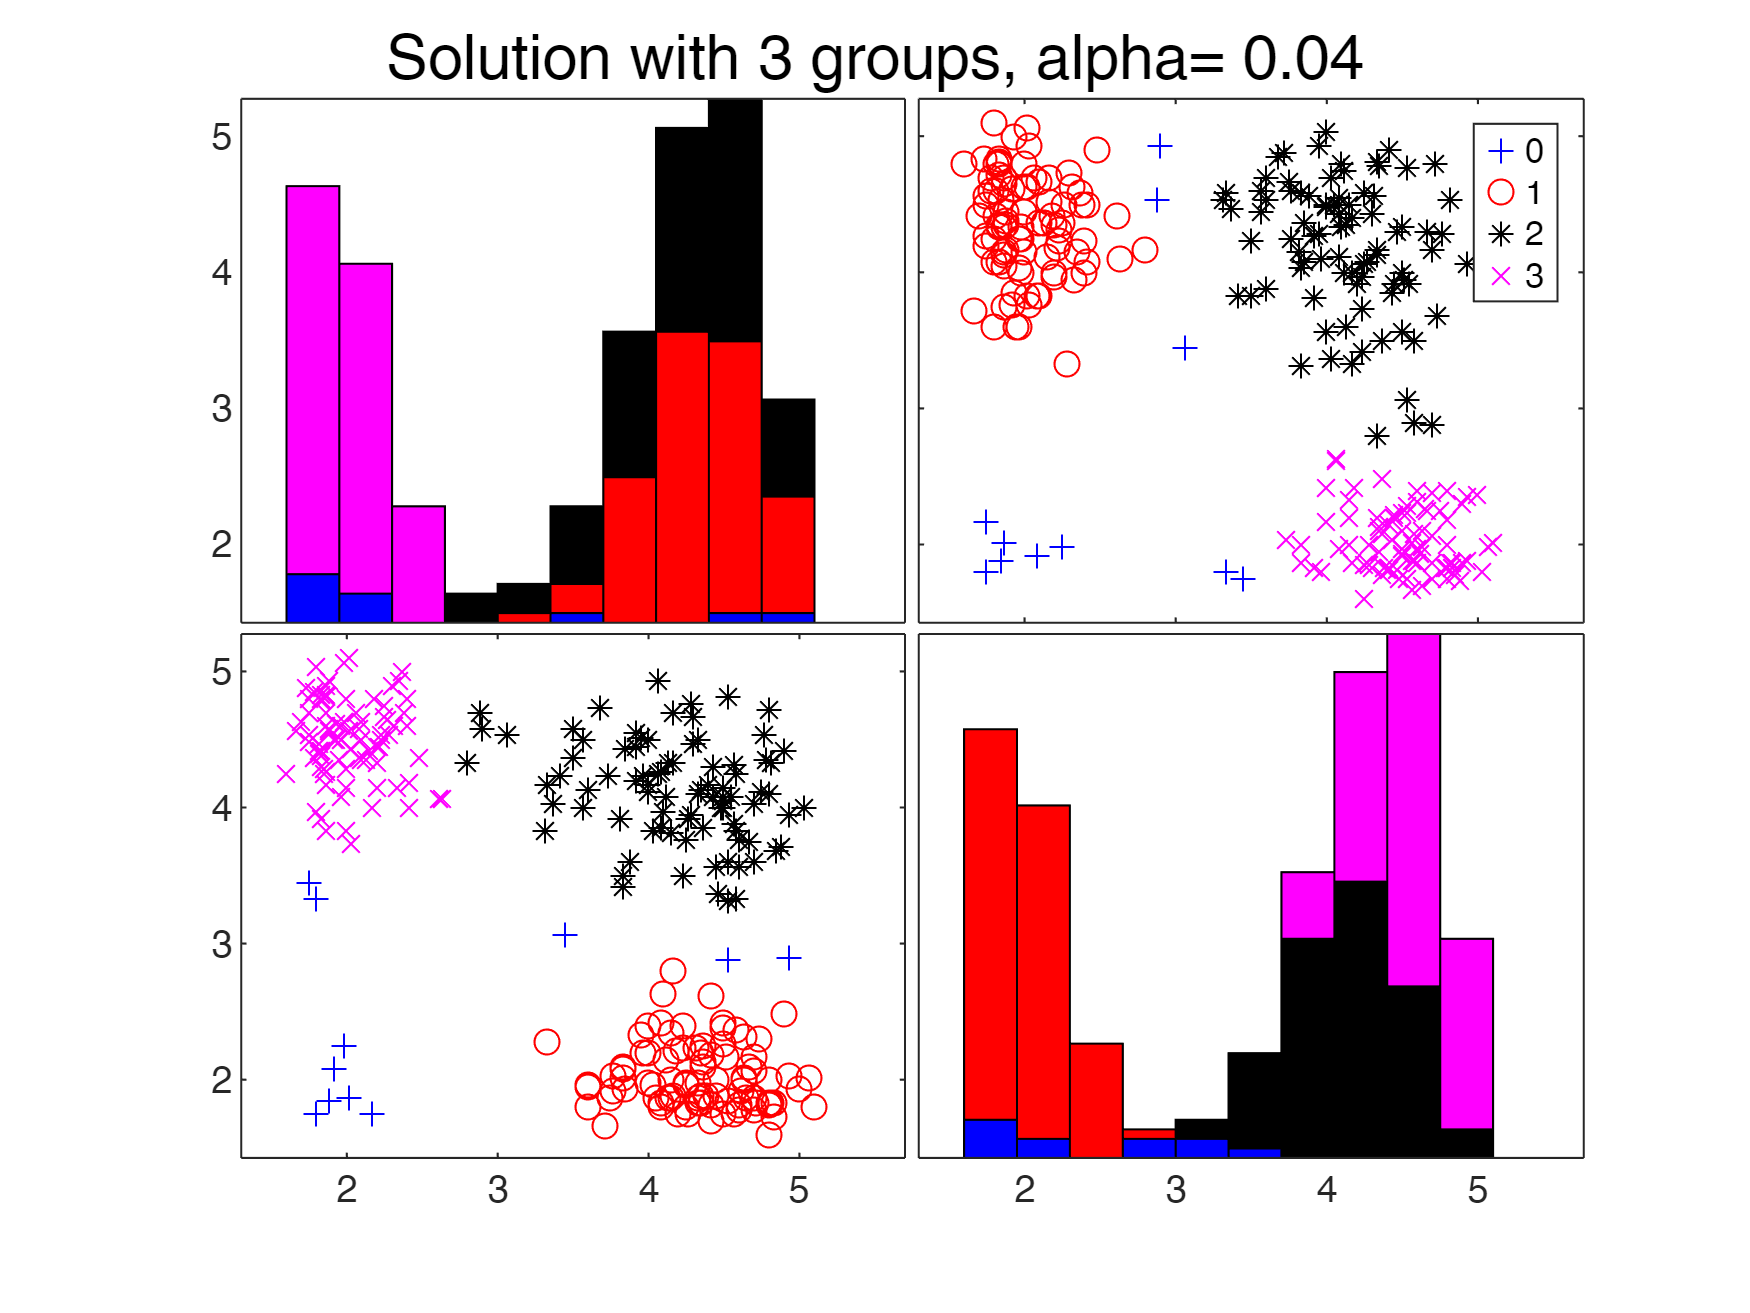

for j=Sol(:,2)'

    solj=Sol(:,2)==j;
    spmplot(Y,'group',SolIdx(:,solj) ,'tag',['pl' num2str(j)]);
    sgtitle(['Solution with ' num2str(Sol(solj,2)) ' groups, alpha= ' num2str(Sol(solj,3))])
end